clear all
close all
clc

Kp = 1;
Ki = 0;

PI = PIController_vel(0.001,Kp);
PI.initialize;
s=tf('s');
pi = Kp*(1+Ki/s);
piz = c2d(pi,0.001);
G = 20*(5*s+1)/(1+s)/(1+10*s)

G =
 
     100 s + 20
  -----------------
  10 s^2 + 11 s + 1
 
Continuous-time transfer function.



%G = 1/(1+s)
Gz =c2d(G,0.001);
figure
opt = stepDataOptions('StepAmplitude',1);
%step(feedback(pi*G,1),opt)
step(feedback(pi*G,1),60,opt)
%step(G,60,opt)
hold on
[yz,t]=step(feedback(piz*Gz,1),60,opt);
%[yz,t]=step(Gz,60,opt);
plot(t,yz,'-*b')


numC0d = Gz.Numerator{1};
denC0d = Gz.Denominator{1};
numC0d = numC0d/denC0d(1);
denC0d = denC0d/denC0d(1);
            
%y/u = B/A
A = -denC0d(2:end); %uscite precenti
B = numC0d; % incressi precedenti
UoutPast = zeros(length(A),1)

UoutPast =      0
     0


UinPast = zeros(length(B),1)

UinPast =      0
     0
     0


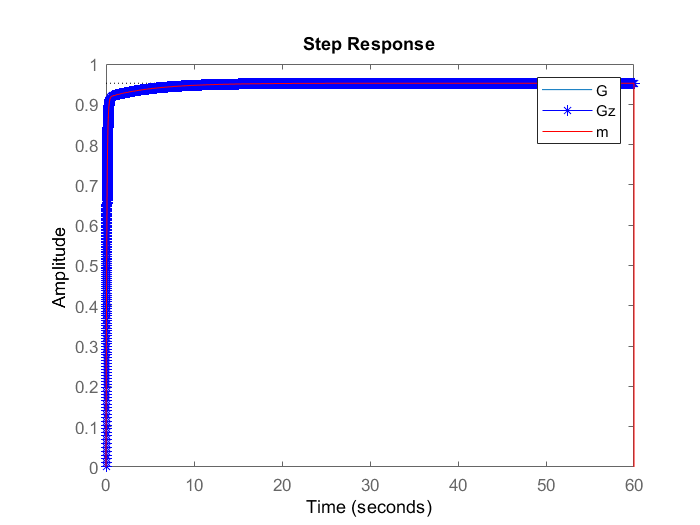



testREF = ones(1,60001);
y = zeros(1,60001);
ucontrol = zeros(1,60001);

for i =3:1:60000
    %ucontrol(i) = testREF(i);
    ucontrol(i) = PI.computeControlAction(testREF(i),y(i-1));
    %y(i) = (0.49982e-7)*ucontrol(i-1)+(0.49963e-7)*ucontrol(i-2) +1.9989*y(i-1)-0.9989*y(i-2);
    %y(i) = 0.0009995*ucontrol(i) + 0.999*y(i-1);
    
    outcalc = A*UoutPast+B*UinPast;      
    for n = length(UinPast):-1:2
        UinPast(n) = UinPast(n-1);
    end
    UinPast(1) = ucontrol(i);
            
           
    for n = length(UoutPast):-1:2
        UoutPast(n) = UoutPast(n-1);
    end
    UoutPast(1) = outcalc;
    y(i) = outcalc;
end
%figure
%plot(ucontrol)
temp = (0:0.001:60);
plot(temp,y,'-r')
legend("G","Gz","m")

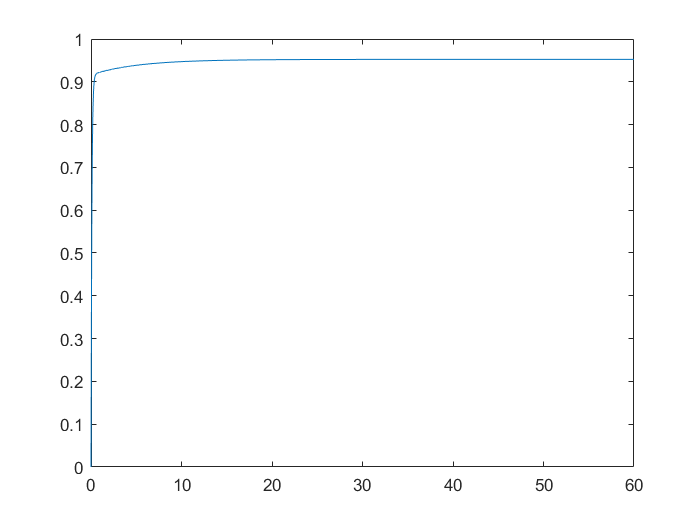

figure
plot(temp(1:end-1),y(1:end-1))

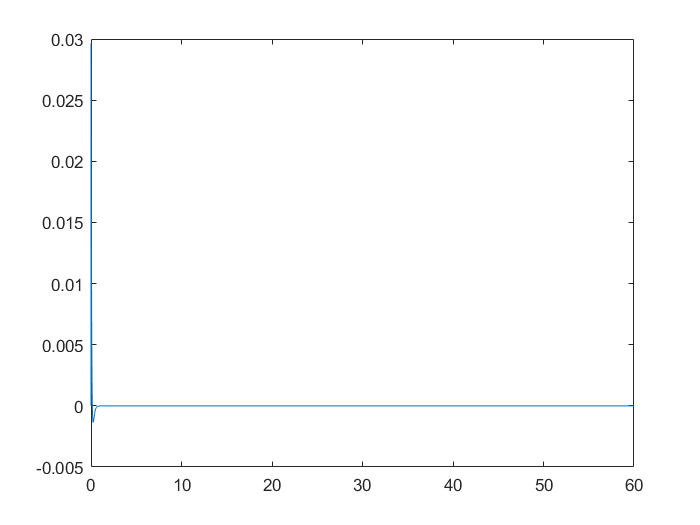

%plot(temp(1:end-1),ucontrol(1:end-1))
plot(temp(1:end-1),yz(1:end-1)'-y(1:end-1))